# Equacions diferencials (I)

#### PVI

f = @(t,y)2*y;  % equació y'=f(t,y)
a = 0;  alpha = 0.1;    % y(a) = alpha
b = 2;  % y(b) = ...

Solució analítica

Y = @(t)exp(2*t)/10;

# Metode d'Euler

h = 0.1;
[t1, YE] = Euler(f, a, b, h, alpha);

w = 0.1000

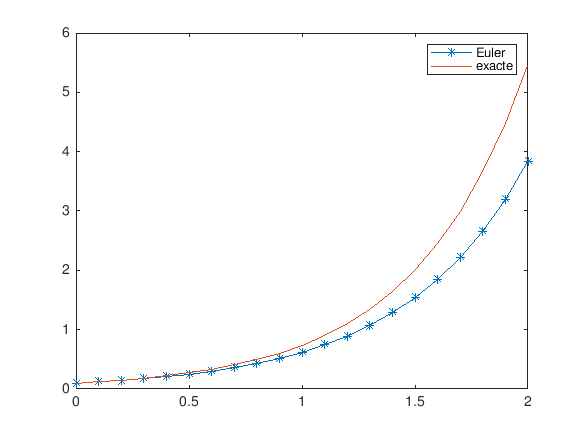

plot(t1, YE, '-*', t1, Y(t1))
legend('Euler', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]'

ans =          0    0.1000    0.1000         0
    0.1000    0.1200    0.1221    0.0021
    0.2000    0.1440    0.1492    0.0052
    0.3000    0.1728    0.1822    0.0094
    0.4000    0.2074    0.2226    0.0152
    0.5000    0.2488    0.2718    0.0230
    0.6000    0.2986    0.3320    0.0334
    0.7000    0.3583    0.4055    0.0472
    0.8000    0.4300    0.4953    0.0653
    0.9000    0.5160    0.6050    0.0890


# Euler Millorat

h = 0.1;
[t1, YE] = EulerMill(f, a, b, h, alpha);

w = 0.1000

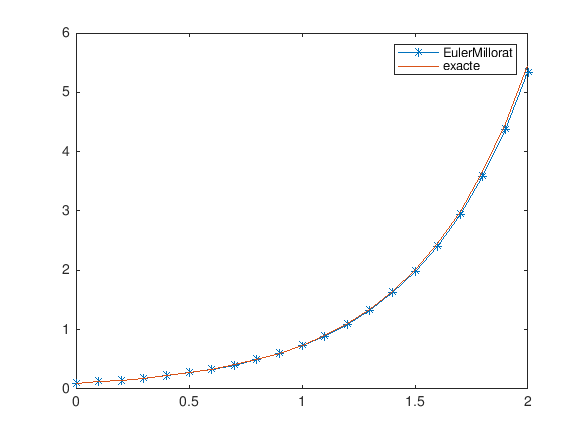

plot(t1, YE, '-*', t1, Y(t1))
legend('EulerMillorat', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]'

ans =          0    0.1000    0.1000         0
    0.1000    0.1220    0.1221    0.0001
    0.2000    0.1488    0.1492    0.0003
    0.3000    0.1816    0.1822    0.0006
    0.4000    0.2215    0.2226    0.0010
    0.5000    0.2703    0.2718    0.0016
    0.6000    0.3297    0.3320    0.0023
    0.7000    0.4023    0.4055    0.0032
    0.8000    0.4908    0.4953    0.0045
    0.9000    0.5987    0.6050    0.0062


# Euler Modificat

h = 0.1;
[t1, YE] = EulerMod(f, a, b, h, alpha);

w = 0.1000

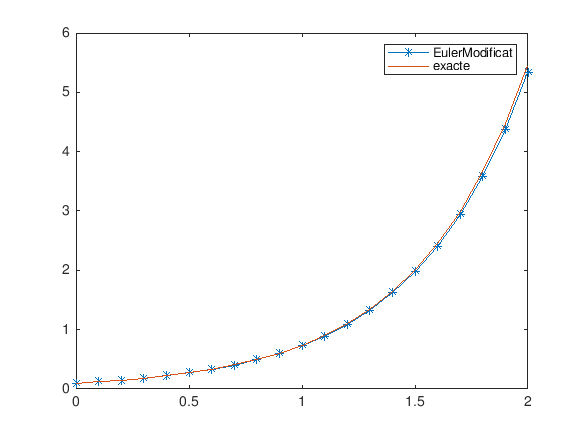

plot(t1, YE, '-*', t1, Y(t1))
legend('EulerModificat', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]'

ans =          0    0.1000    0.1000         0
    0.1000    0.1220    0.1221    0.0001
    0.2000    0.1488    0.1492    0.0003
    0.3000    0.1816    0.1822    0.0006
    0.4000    0.2215    0.2226    0.0010
    0.5000    0.2703    0.2718    0.0016
    0.6000    0.3297    0.3320    0.0023
    0.7000    0.4023    0.4055    0.0032
    0.8000    0.4908    0.4953    0.0045
    0.9000    0.5987    0.6050    0.0062


# RK4

h = 0.1;
[t1, YE] = RK4(f, a, b, h, alpha);

w = 0.1000

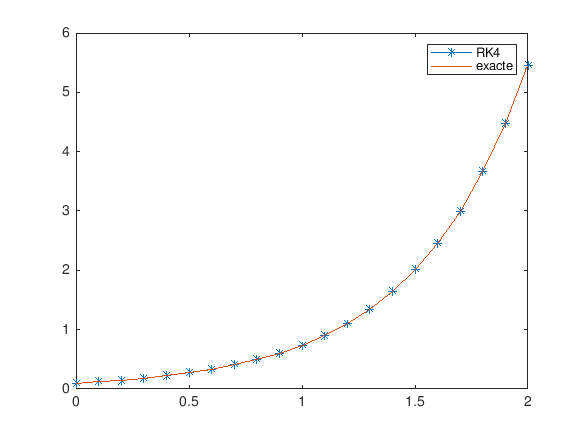

plot(t1, YE, '-*', t1, Y(t1))
legend('RK4', 'exacte')

Error

[t1; YE; Y(t1); abs(YE-Y(t1))]

ans =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000
    0.1000    0.1221    0.1492    0.1822    0.2226    0.2718    0.3320    0.4055    0.4953    0.6050    0.7389    0.9025    1.1023    1.3463    1.6444    2.0085    2.4532    2.9963    3.6597    4.4699    5.4596
    0.1000    0.1221    0.1492    0.1822    0.2226    0.2718    0.3320    0.4055    0.4953    0.6050    0.7389    0.9025    1.1023    1.3464    1.6445    2.0086    2.4533    2.9964    3.6598    4.4701    5.4598
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002
